# 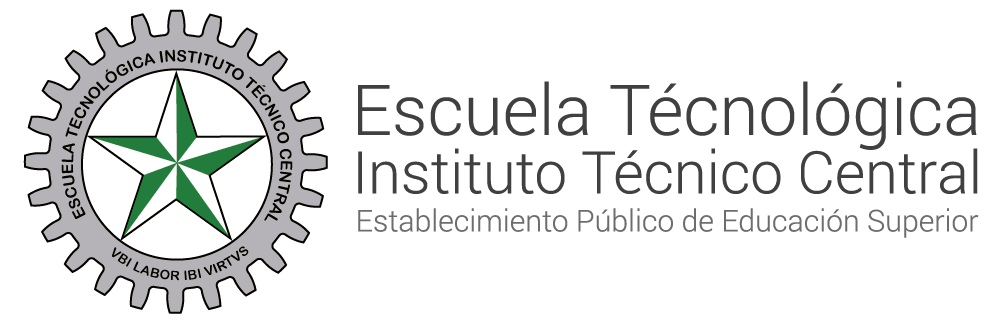

**SISTEMAS DE CONTROL II  **

# **ECUACIONES EN DIFERENCIAS**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Coautor: KAREN JULIEHT SANCHEZ

# **OBJETIVO:**

Comprender y aplicar el concepto de representación de sistemas mediante la transformada Z, así como la **solución de ecuaciones en diferencias**, para analizar y diseñar sistemas de control en el dominio discreto.

# **Ejercicios 1**

Resuelva la siguiente ecuacion en diferencias para la variable de salida X(z)


$$x\left(k+2\right)-x\left(k\right)=0$$


Con condiciones iniciales $x\left(0\right)=1\;\;\;\;,\;\;x\left(1\right)=0$

## Paso a Paso

## Paso 1

1.Transformar la ecuación en diferencias al dominio de *z *mediante la transformada, mediante la tabla anterior: 

        
$$\textrm{La}\;\textrm{transformada}\;\textrm{de}:x\;\left(k+2\right)\;\textrm{es}\;z^2 X\left(z\right)-z^2 x\left(0\right)-\textrm{zx}\left(1\right)$$


        
$$\textrm{La}\;t\textrm{ransformada}\;\textrm{de}:x\;\left(k\right)\;\textrm{es}\;X\left(z\right)$$


Sustituyendo, tenemos:


$$z^2 X\left(z\right)-z^2 x\left(0\right)-\textrm{zx}\left(1\right)-X\left(z\right)=0$$


## Paso 2

2. Manipular las ecuaciones algebraicas transformadas y resolverlas para la variable de salida.

Aplicamos la transformada Z a la ecuacion, recordando que: 


$$z\left\lbrace x\left(k+2\right)\right\rbrace =z^2 X\left(z\right)-z^2 x\left(0\right)-\textrm{zx}\left(1\right)$$



$$Z\left\lbrace x\left(k\right)\right\rbrace =X\left(z\right)$$


Sustituimos: 


$$z^2 X\left(z\right)-z^2 x\left(0\right)-\textrm{zx}\left(1\right)-X\left(z\right)=0$$


Despejamos X(z)


$$X\left(z\right)\left(z^2 -1\right)=z^2 x\left(0\right)+\textrm{zx}\left(1\right)$$


Sustituimos las condciones iniciales: 


$$X\left(z\right)\left(z^2 -1\right)=z^2 \left(1\right)+z\left(0\right)$$



$$X\left(z\right)=\frac{z^2 }{z^2 -1}$$


## **Paso 3**

3. Realizar la expansión en fracciones parciales de la ecuación algebraica transformada.

A continuacion, en el siguiente codigo podemos obtener la expansion de fracciones parciales, adecuando los resultados obtenidos en el numerador y denominador. 

b1 = [1 0 0];
a1 = [1 0 -1];
b = b1;
a = a1;
[r,p,k] = residuez(b,a)

r =     0.5000
    0.5000


p =     -1
     1


k = 0

Y_z_fract=simplify((r(1)/(1-(p(1)*z^(-1)))))+simplify((r(2)/(1-(p(2)*z^(-1)))))

$$Y\_z\_fract = \frac{z}{2\,\left(z-1\right)}+\frac{z}{2\,\left(z+1\right)}$$

## Paso 4

4. Obtener la transformada inversa Z.

A continuacion, el siguiente codigo lo empleamos para hallar la inversa de la transformada Z obtenida en el paso anterior. 

%% Codigo para hallar la inversa de la transformada Z
syms k;
simplify(iztrans(Y_z_fract,z,k))

$$ans = \frac{{\left(-1\right)}^{k}}{2}+\frac{1}{2}$$

## Paso 5

A continuacion, en el siguiente codigo obtenemos la grafica de la solucion de la ecuacion: 

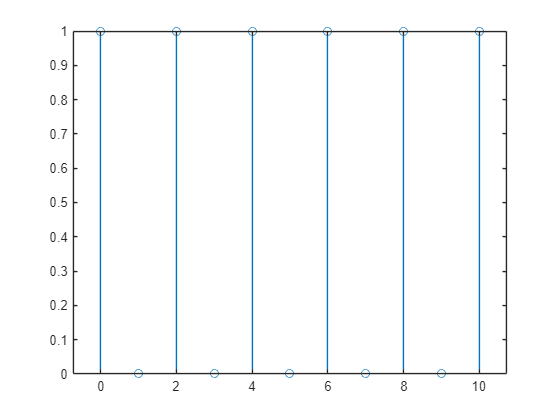

t = 0:1:10; 
y_t=(-1).^t/2+(1/2);
stem(t,y_t)

# **Ejercicio 2**

- Resuelva la siguiente ecuacion en diferencias para la variable de salida X(z)


$$x\left(k+2\right)-x\left(k+1\right)+0,1x\left(k\right)=u\left(k\right)$$


## Paso a Paso

#### Paso 1

1.Transformar la ecuación en diferencias al dominio de *z *mediante la transformada, mediante la tabla anterior: 

        
$$\textrm{La}\;\textrm{transformada}\;\textrm{de}:x\;\left(k+2\right)\;\textrm{es}\;z^2 X\left(z\right)-z^2 x\left(0\right)-\textrm{zx}\left(1\right)$$


        
$$\mathrm{La}\;\mathrm{transformada}\;\mathrm{de}:x\;\left(k+1\right)\;\mathrm{es}\;\mathrm{zX}\left(z\right)-\mathrm{zx}\left(0\right)$$


        
$$\mathrm{La}\;\mathrm{transformada}\;\mathrm{de}:x\;\left(k\right)\;\mathrm{es}\;X\left(z\right)$$


        
$$\mathrm{La}\;\mathrm{transformada}\;\mathrm{de}:u\left(k\right)\;\mathrm{es}\;U\left(z\right)$$


Sustituyendo, tenemos:


$$z^2 X\left(z\right)-\mathrm{zX}\left(z\right)+0,1X\left(z\right)=U\left(z\right)\;$$


#### Paso 2

2. Manipular las ecuaciones algebraicas transformadas y resolverlas para la variable de salida.

Simplificamos: 


$$z^2 X\left(z\right)-\mathrm{zX}\left(z\right)+0,1X\left(z\right)=U\left(z\right)\;$$


Agrupamos en terminos de X(z)


$$X\left(z\right)\left(z^2 -z+0,1\right)=U\left(z\right)$$


Despejamos X(z):


$$X\left(z\right)=\frac{\frac{z}{z-1}}{z^2 -z+0,1}$$
 

**Paso 3**

3. Realizar la expansión en fracciones parciales de la ecuación algebraica transformada.

A continuacion, en el siguiente codigo podemos obtener la expansion de fracciones parciales, adecuando los resultados obtenidos en el numerador y denominador. 

b1 = [1 0];
a1 = [1 -1 0.1];
    a2= [1 -1];
b = b1;
a = conv(a1,a2);
[r,p,k] = residue(b,a)

r =    10.0000
  -10.1640
    0.1640


p =     1.0000
    0.8873
    0.1127



k =

     []



#### Paso 4

4. Obtener la transformada inversa Z.

A continuacion, el siguiente codigo lo empleamos para hallar la inversa de la transformada Z obtenida en el paso anterior. 

syms z
Y_z_fract=simplify((r(1)/(1-(p(1)*z^(-1)))))+simplify((r(2)/(1-(p(2)*z^(-1)))))+simplify((r(3)/(1-(p(3)*z^(-1)))))

$$Y\_z\_fract = \frac{10\,z}{z-1}+\frac{5907922689626651\,z}{36028797018963968\,z-4060505425648497}-\frac{91548973219814720\,z}{9007199254740992\,z-7992072898328865}$$

syms k;
simplify(iztrans(Y_z_fract,z,k))

$$ans = \frac{5907922689626651\,{\left(\frac{4060505425648497}{36028797018963968}\right)}^{k}}{36028797018963968}-\frac{1430452706559605\,{\left(\frac{7992072898328865}{9007199254740992}\right)}^{k}}{140737488355328}+10$$